## **Punto Fijo**

Se debe cumplir dos condiciones:

- La derivada de g debe ser menor que 1

- Para todo x en el intervalo, g(x) debe estar en el intervalo

syms x
% matlabFunction lo que hace es convertir una expresión en una función
g = matlabFunction(x.^2);
dg = diff(g(x));

$$dg = 2\,x$$


% converitmos dg en función
fudg = matlabFunction(dg);

xx = 0.64:0.01:1.44;
yy1 = abs(fudg(xx));

plot(xx, yy1, 'b');
grid on

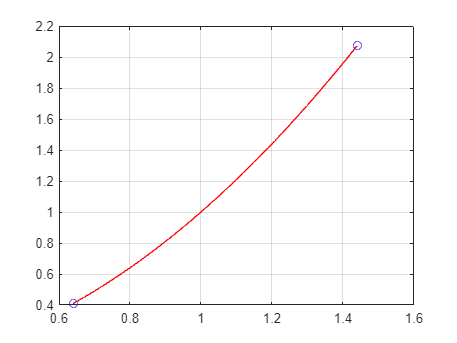

% Validar si la función x^2 cumple con la segunda condición
g = matlabFunction(x.^2);

xx = 0.64:0.01:1.44;
yy = g(xx);
plot(xx, yy, 'r', [0.64 1.44], [g(0.64), g(1.44)], 'ob');
grid on

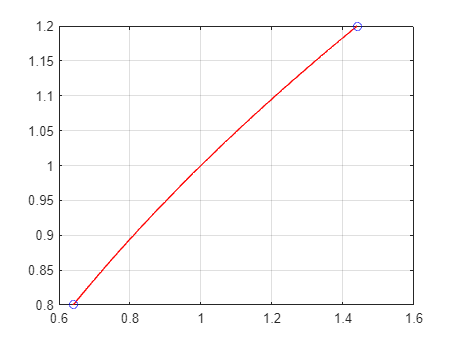

% Validar si la función sqrt(x) cumple con la segunda condición
syms x
g = matlabFunction(sqrt(x));

xx = 0.64:0.01:1.44;
yy = g(xx);
plot(xx, yy, 'r', [0.64 1.44], [g(0.64), g(1.44)], 'ob');
grid on

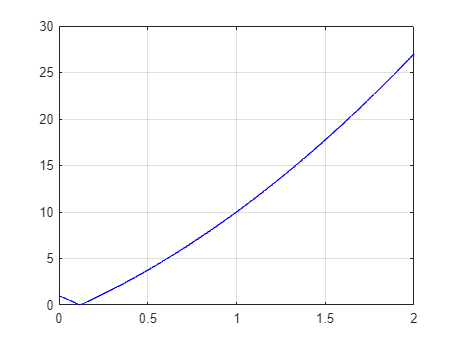

% para la primera condición de la derivada
syms x
g = matlabFunction(x - x^3 - 4*x^2 + 10);

dg = diff(g(x));

fudg = matlabFunction(dg);
xx = 0:0.01:2;
yy1 = abs(fudg(xx));

plot(xx, yy1, 'b');
grid on

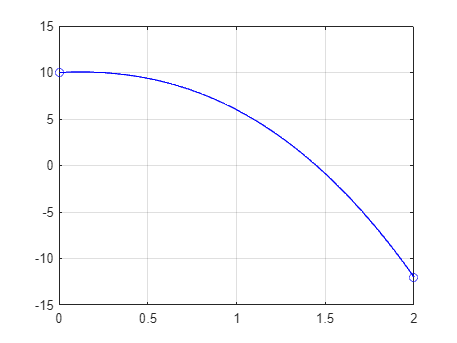

g = matlabFunction(x - x^3 - 4*x^2 + 10);

xx = 0:0.01:2;
yy = g(xx);
plot(xx, yy, 'b', [0 2], [g(0) g(2)], 'ob');
grid on

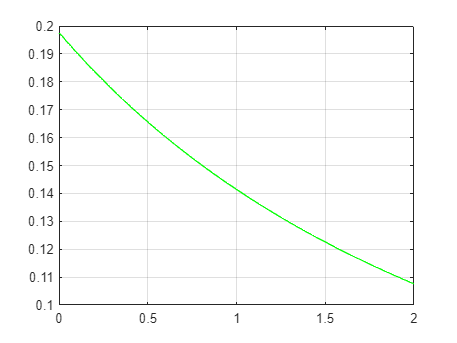

% para la primera condición de la derivada
syms x
g = matlabFunction(sqrt(10/(x+4)));

dg = diff(g(x));

fudg = matlabFunction(dg);
xx = 0:0.01:2;
yy1 = abs(fudg(xx));

plot(xx, yy1, 'g');
grid on

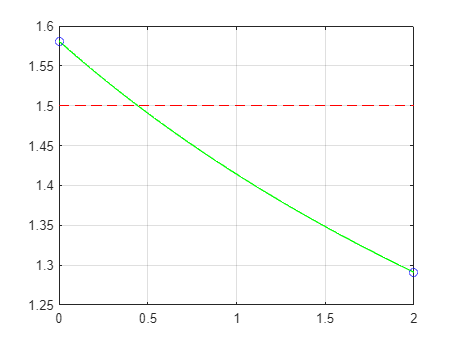

syms x
g = matlabFunction(sqrt(10/(x+4)));

xx = 0:0.01:2;
yy = g(xx);
plot(xx, yy, 'g', [0 2], [g(0) g(2)], 'ob');
grid on
hold on

plot(xx, 1.5* ones(size(xx)), '--r');

hold off

Proceso iterativo del punto fijo

pfijo(g, 1.2, 20)

## Bisección

Ojito

%z = biseccion2(g, 0, 2, 100)

ans =    1.200000000000000
   1.386750490563073
   1.362500185445018
   1.365577460385760
   1.365185810090544
   1.365235637411275
   1.365229297876861
   1.365230104451481
   1.365230001831465
   1.365230014887748


z = newton(g, 0.5, 50)

Función de Punto Fijo

function z = pfijo(g, x0, Maxiter)

z =    0.500000000000000


    z = [x0];
    
    for k = 1:Maxiter
        x1 = g(x0);
        z = [z; x1];
        x0 = x1;
    end
end

Función de Bisección

function z = biseccion2(f,a,b,Tol)
    c = (a+b)/2;
    error = (b-a)/2;
    z = [a b c f(a) f(b) f(c) error];
    N = ceil(log((b-a)/(2*Tol))/log(2));
    fprintf('Se necesita %d iteraciones\n', N)
    
    while error > Tol
        if f(a)*f(c)<0
            b = c;
        else
            a=c;
        end

    c = (a+b)/2;
    error = (b-a)/2;
    z = [z; a b c f(a) f(b) f(c) error];
    end
end

Función de newton

function z=newton(f,x0,Tol)
    syms x
    df = diff(f(x));
    dfu = matlabFunction(df);
    z = x0;
    error = 1;

    while error>Tol
        x1 = x0-f(x0)/dfu(x0);
        z = [z;x1];
        error = abs(x1-x0)/abs(x1);
        x0 = x1;
    end
end